%% Loading the data:
clearvars; close all; clc  
weather_data = readtable("weather_2016_2020_daily.csv");
powerusage_data = readtable("power_usage_2016_to_2020.csv");

%% Checking the time step sizes:

% The timesteps does not seem to be in correct order, so we can consider
% the need of sorting the data.
% Remove header rows first and sort:
wd_time = weather_data(:,1);
[wd_time_sorted,idx] = sort([wd_time{:,1}],'ascend');
wd_sorted = weather_data(idx,:);

pd_time = powerusage_data(:,1);
[pd_time_sorted,idx] = sort([pd_time{:,1}],'ascend');
pd_sorted = powerusage_data(idx,:);
% When looking at the time steps we have in the datasets, they are not
% fully comparable because the power usage data has time step of 1 hour,
% and weather time data has time step of 1 day (average of the day).
% Another issue is that the datasets does not seem to have all of the dates
% available, so visualizations might


%% Finding missing dates:

% For power data 
power_data_range = pd_time_sorted(1):hours(1):pd_time_sorted(end);
power_missingdates = setdiff(power_data_range,pd_time_sorted);

% For weather data:
weather_data_range = wd_time_sorted(1):wd_time_sorted(end);
weather_missingdates = setdiff(weather_data_range,wd_time_sorted);

% Initial results indicate that only years 2016 and 2020 contains missing
% values, thus to be able to get good visualizations and continous
% representation of data for modeling purposes we will exclude those years
% out.

% New datasets:

% Indeces to exclude
excludeYears = [2016,2020];
powerExcludeInd = ismember(year(pd_time_sorted),excludeYears);
powerusage_data_new = pd_sorted(~powerExcludeInd,:);

weatherExcludeInd = ismember(year(wd_time_sorted),excludeYears);
weather_data_new = wd_sorted(~weatherExcludeInd,:);


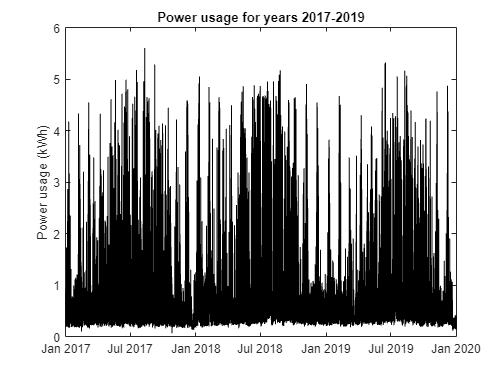

%% Initial visualizations:

datetime_weather = [weather_data_new{:,1}];
datetime_power = [powerusage_data_new{:,1}];
power_data = [powerusage_data_new{:,2}];
plot(datetime_power,power_data,'k-')
ylabel('Power usage (kWh)')
title('Power usage for years 2017-2019')

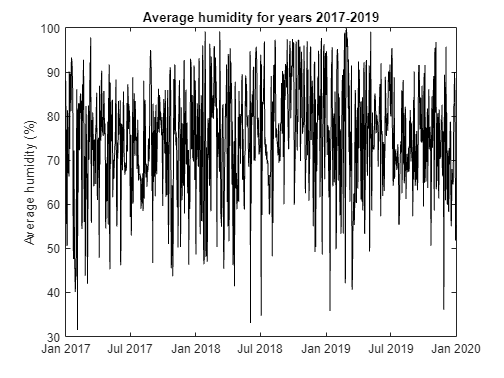



% Converting the data to celsius for easier comparison
figure
weather_avg_hum_data = [weather_data_new{:,10}];
plot(datetime_weather,weather_avg_hum_data,'k-')
ylabel('Average humidity (%)')
title('Average humidity for years 2017-2019')

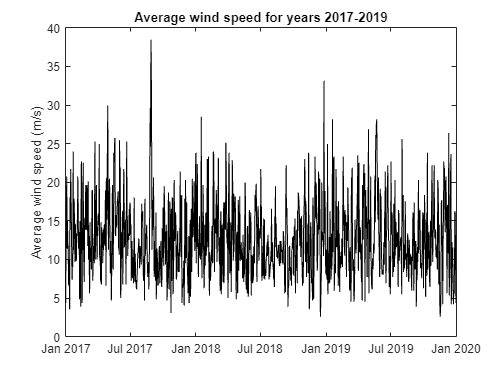


figure
weather_avg_wind_data = [weather_data_new{:,13}]*1.6093;
plot(datetime_weather,weather_avg_wind_data,'k-')
ylabel('Average wind speed (m/s)')
title('Average wind speed for years 2017-2019')

## Calculating correlations between average daily consumption and the other explanatory variables


timestamps = [powerusage_data_new{:,1}];
daily_averages = weather_data_new;
daily_averages.AvgPower = zeros(size(daily_averages, 1), 1);
dayind = 1;
cumulative_value = 0;
% Adding daily average power usages to the table:
for i = 1:1:length(timestamps)
    hourstamp = hour(timestamps(i));
    cumulative_value = cumulative_value + powerusage_data_new{i,2};
    if(hourstamp==23)
        daily_averages.AvgPower(dayind) = cumulative_value/24;
        dayind = dayind+1;
        cumulative_value = 0;
    end
end

% Choosing only the average values for different features to plot
column_ind = [4,7,10,13,16,18,19,20]

column_ind =      4     7    10    13    16    18    19    20


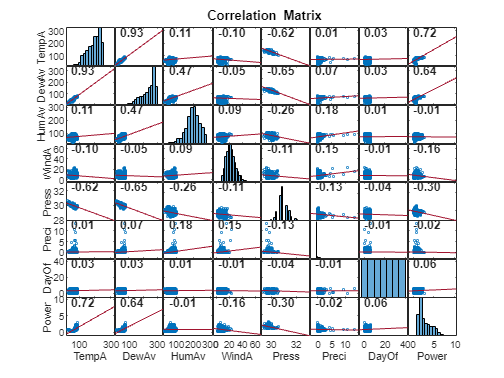

column_names = ["TempAvg","DewAvg","HumAvg","WindAvg","PressAvg","Precipitation","DayOfWeek","PowerAvg"];
corrplot([daily_averages{:,column_ind}],"VarNames",column_names)

## Distribution plots for the power:

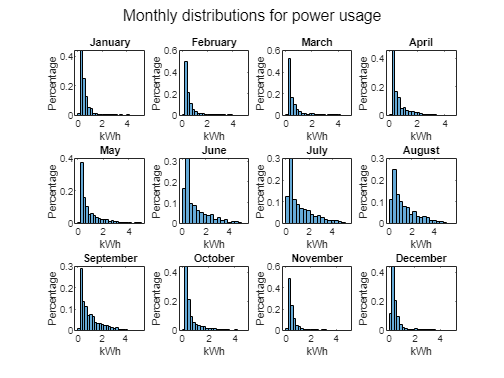

monthList = ["January","February","March","April","May","June","July","August","September","October","November","December"];
for i = 1:1:12
    subplot(3,4,i)
    monthInd = month([powerusage_data_new{:,1}])==i;
    histogram([powerusage_data_new{monthInd,2}],'Normalization','probability')
    title(monthList(i))
    ylabel('Percentage')
    xlabel('kWh')
end
sgtitle('Monthly distributions for power usage')

figure
dayList = ["Monday","Tuesday","Wednesday","Thursday","Friday","Saturday","Sunday"]

dayList = 1×7 string array
    "Monday"    "Tuesday"    "Wednesday"    "Thursday"    "Friday"    "Saturday"    "Sunday"


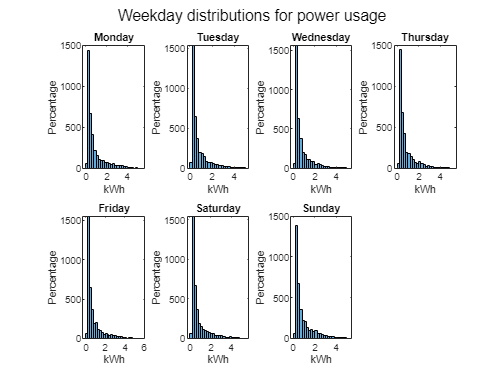

for i = 1:1:7
    subplot(2,4,i)
    dayInd = weekday([powerusage_data_new{:,1}])==i;
    histogram([powerusage_data_new{dayInd,2}])
    title(dayList(i))
    ylabel('Percentage')
    xlabel('kWh')
end
sgtitle('Weekday distributions for power usage')

## Finding trends for the power usage:



% Decomposing in own section:

power_table = table(power_data);
decomp_power = trenddecomp(power_table);
decomp_power = addvars(decomp_power,power_table);
decomp_power = table2timetable(decomp_power,"RowTimes",datetime_power);

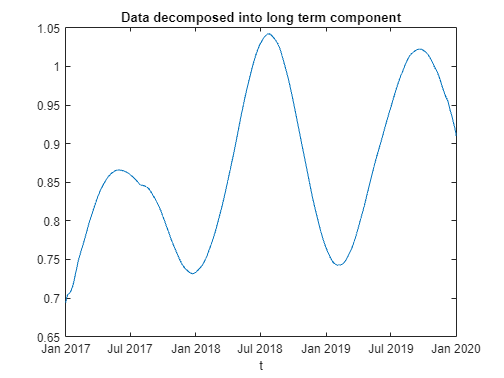


figure
plot(decomp_power.Time,decomp_power.power_data_LongTerm)
title('Data decomposed into long term component')
xlabel('t')

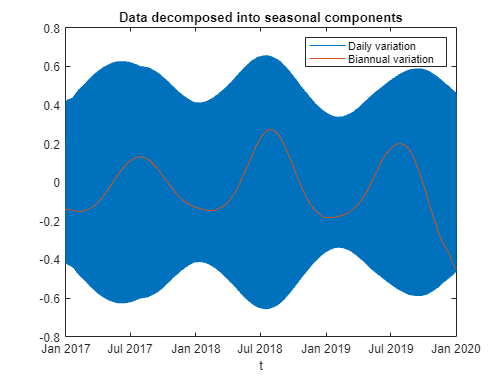

figure
plot(decomp_power.Time,decomp_power.power_data_Seasonal)
title('Data decomposed into seasonal components')
xlabel('t')
legend('Daily variation','Biannual variation')

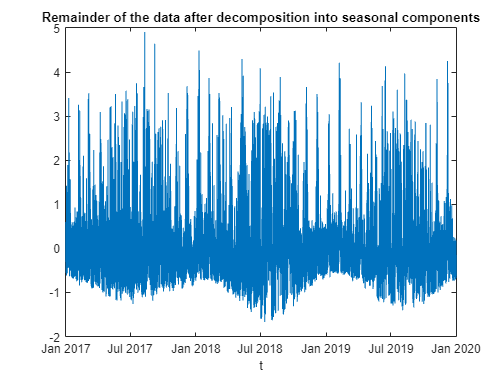


plot(decomp_power.Time,decomp_power.power_data_Remainder)
title('Remainder of the data after decomposition into seasonal components')
xlabel('t')

**Finding outliers using STL in Trenddecopm:**



% Decomposing in own section:

power_table = table(power_data);
decomp_power = trenddecomp(power_table,"stl",[1*24 1*24*365/2]);
decomp_power = addvars(decomp_power,power_table);
decomp_power = table2timetable(decomp_power,"RowTimes",datetime_power);

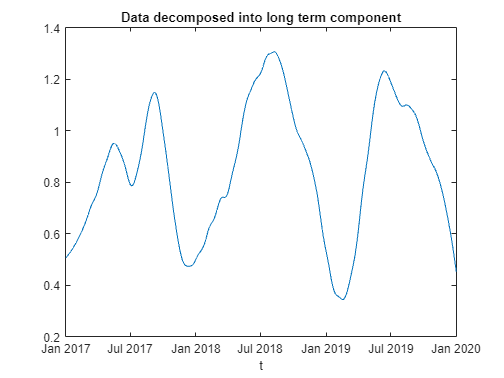

figure
plot(decomp_power.Time,decomp_power.power_data_LongTerm)
title('Data decomposed into long term component')
xlabel('t')

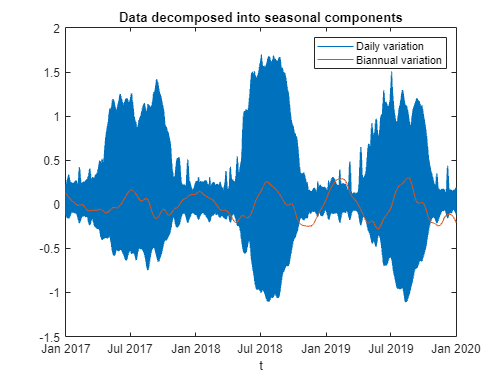

figure
plot(decomp_power.Time,decomp_power.power_data_Seasonal)
title('Data decomposed into seasonal components')
xlabel('t')
legend('Daily variation','Biannual variation')

close all
plot(decomp_power.Time,decomp_power.power_data_Remainder)

Unable to resolve the name 'decomp_power.Time'.

title('Remainder of the data after decomposition into seasonal components')
xlabel('t')


% Sliding window for outlier detection:
wsize = 1*24*30;
outlier_list = isoutlier(decomp_power.power_data_Remainder,"movmean",wsize);

% Commented out if own code needed for further investigation
% for i = 1:wsize:length(decomp_power.power_data_Remainder)-wsize;
%     cur_window = decomp_power.power_data_Remainder(w_ind:w_ind+wsize);
%     w_std = std(cur_window);
%     for j = 1:1:length(cur_window)
%         cur_value = cur_window(j);
% 
%         if(w_std-2.5*w_std<cur_value && cur_value<w_std+2.5*w_std)
%             continue
%         else
%             outlier_list(end+1) = i+j-1;
%         end
%     end
% 
% end
hold on
plot(decomp_power.Time(outlier_list),decomp_power.power_data_Remainder(outlier_list),'r*')
legend("Remainder after decomposition","Possible outliers")


% Control lines with STD of 2 and 3:

remainder_STD = std(decomp_power.power_data_Remainder)

figure
hold on
plot(decomp_power.Time,decomp_power.power_data_Remainder)
title('Remainder of the data after decomposition into seasonal components')
plot([decomp_power.Time(1) decomp_power.Time(end)], [remainder_STD+remainder_STD*2 remainder_STD+remainder_STD*2],'r-')
plot([decomp_power.Time(1) decomp_power.Time(end)], [remainder_STD+remainder_STD*3 remainder_STD+remainder_STD*3],'g-')
plot([decomp_power.Time(1) decomp_power.Time(end)], [remainder_STD-remainder_STD*2 remainder_STD-remainder_STD*2],'r-')
plot([decomp_power.Time(1) decomp_power.Time(end)], [remainder_STD+-remainder_STD*3 remainder_STD+-remainder_STD*3],'g-')
legend('Remainder after decomposition','2 STD control line','3 STD control line')


## RNN Modeling:

% All of the data is found in daily_averages variable, where the last
% column is the variable to model.

% Feature selection
features = daily_averages(:, {'AvgPower', 'Temp_avg', 'Press_avg','Dew_avg'});

% Normalizing the features
mu = mean(features{:,:});
sig = std(features{:,:});
features{:,:} = (features{:,:} - mu) ./ sig;

% Shifting the target variable to create the 'previous day power usage' feature
features.previousDayPowerUsage = [nan; features{1:end-1, 1}];

% Removing the first row with NaN
features(1, :) = [];

% Preparing data for LSTM
X = features{:, 2:end};
y = features{:, 1};

% Reshaping data for LSTM
numObservations = size(X, 1);
numFeatures = size(X, 2);
numTimeSteps = 1;
X = reshape(X', [numFeatures , numObservations]);
y = reshape(y, [1, numObservations]);
% Spliting data into training and test sets
numTimeStepsTrain = floor(0.8 * numObservations);
dateTrain = [daily_averages.Date(1:numTimeStepsTrain,1)];
dateTest = [daily_averages.Date(numTimeStepsTrain+1:end-1,1)];
XTrain = X(:, 1:numTimeStepsTrain);
yTrain = y(:, 1:numTimeStepsTrain);
XTest = X(:, numTimeStepsTrain+1:end);
yTest = y(:, numTimeStepsTrain+1:end);

net     = layrecnet(5:9,[10],'train');
net.trainParam.lr = 0.001

net =

    Neural Network
 
              name: 'Layer Recurrent Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 9
 numFeedbackDelays: 9
 numWeightElements: 510
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input

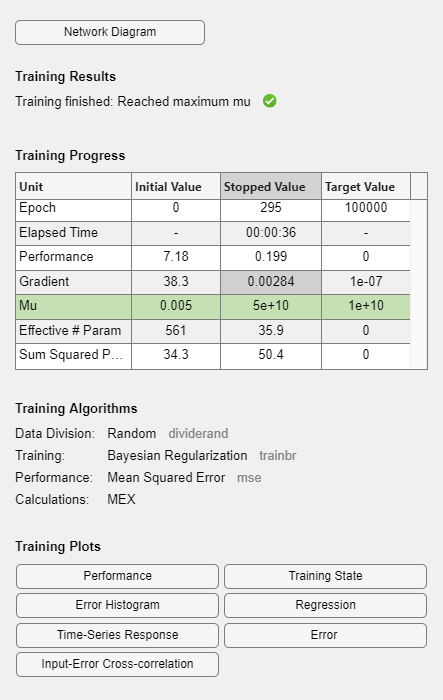

net.trainParam.epochs = 100000;
trainedNet = train(net,XTrain,yTrain);


YPred           = trainedNet(XTest);

% Calculating RMSE
rmse = sqrt(mean((YPred - yTest).^2))

rmse = 0.5039

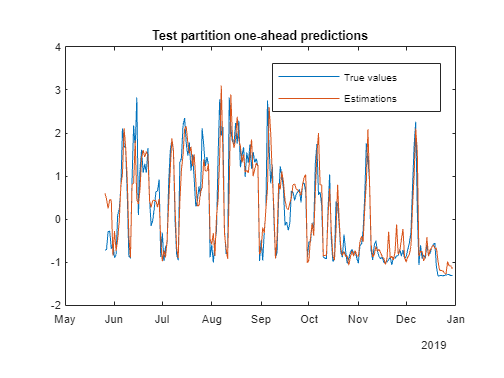


% Plots of the prediction:
figure; 
nexttile;
plot(dateTest,yTest);
hold on 
plot(dateTest,YPred);
title("Test partition one-ahead predictions");
legend('True values','Estimations')